net = network_IEEE68bus;

time = [0,10,20,60];

%Changing initial value of 2nd state(omega) of 3rd bus
bus_idx   = 3; 
state_idx = 2; 
idx = 0;
for i = 1:bus_idx-1
    idx = idx+net.a_bus{i}.component.get_nx;
end
idx = idx+state_idx;

option          = struct();
option.x0_sys  = net.x_equilibrium;
option.x0_sys(idx)= option.x0_sys(idx) + 0.01;

%Introducing fault
option.fault = {{[0 0.07], 1}, {[15 15.05], 1}, {[10,10.01],[2,5:7]}};

%Introducing load
u_idx = 20;
u = [0, 0.05, 0.1, 0.1;...
     0,    0,   0,   0];

%simulate
out = net.simulate(time,u, u_idx,option);

0|                                                                                                    |60
 |=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>|


%Identify component type
bus_num = numel(net.a_bus);
component_idx = zeros(1,bus_num);
%Depends on class names of components, assign numbers
for idx = 1:bus_num
    switch class(net.a_bus{idx}.component) %can return class names of buses
        case 'generator_1axis'
            component_idx(idx) = 1;
        case 'load_impedance'
            component_idx(idx) = 2;
        case 'component_empty'
            component_idx(idx) = 3;
    end
end

generator_idx = find(component_idx==1);

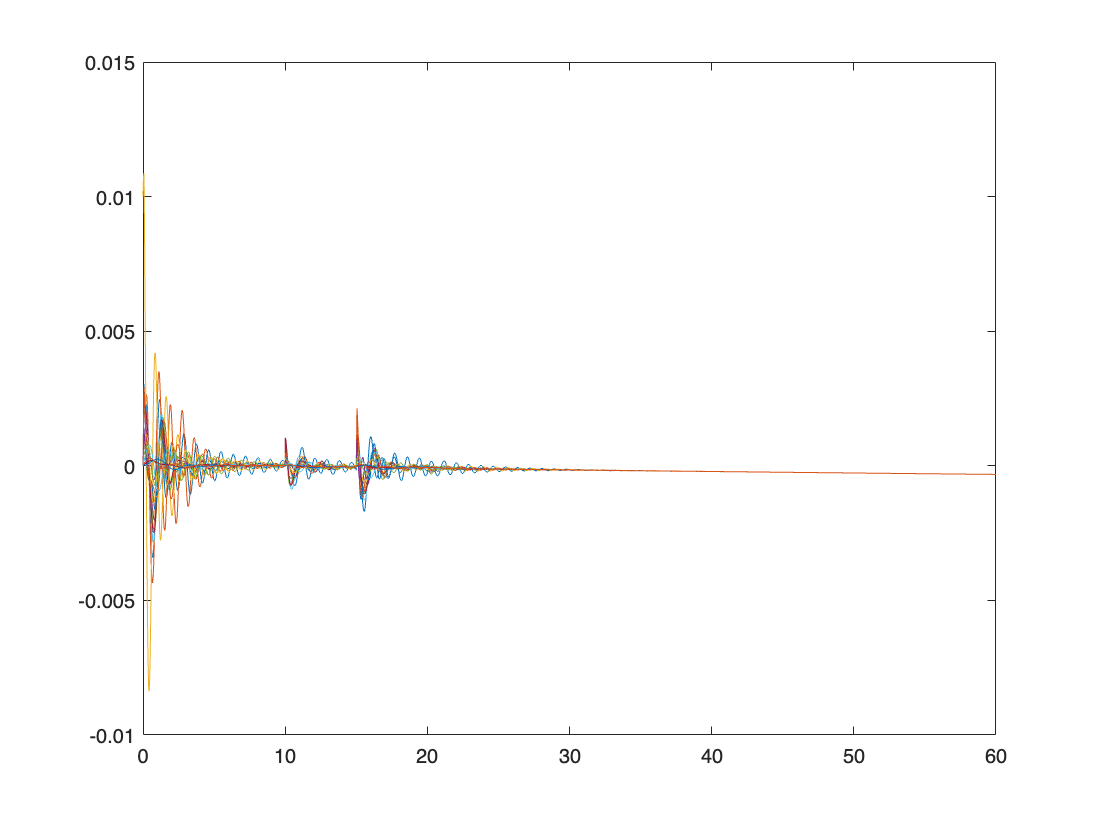

%Get graph for frequency deviation of all generators
n = numel(generator_idx);
for i = 1:n
    plot(out.t,out.X{i}(:,2));
    hold on;
end

%Add AGC controller
con = controller_broadcast_PI_AGC(net,1:16,1:16,-10,-500);

net.add_controller_global(con);

%simulate again
out1 = net.simulate(time,u, u_idx,option);

0|                                                                                                    |60
 |=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>=>|


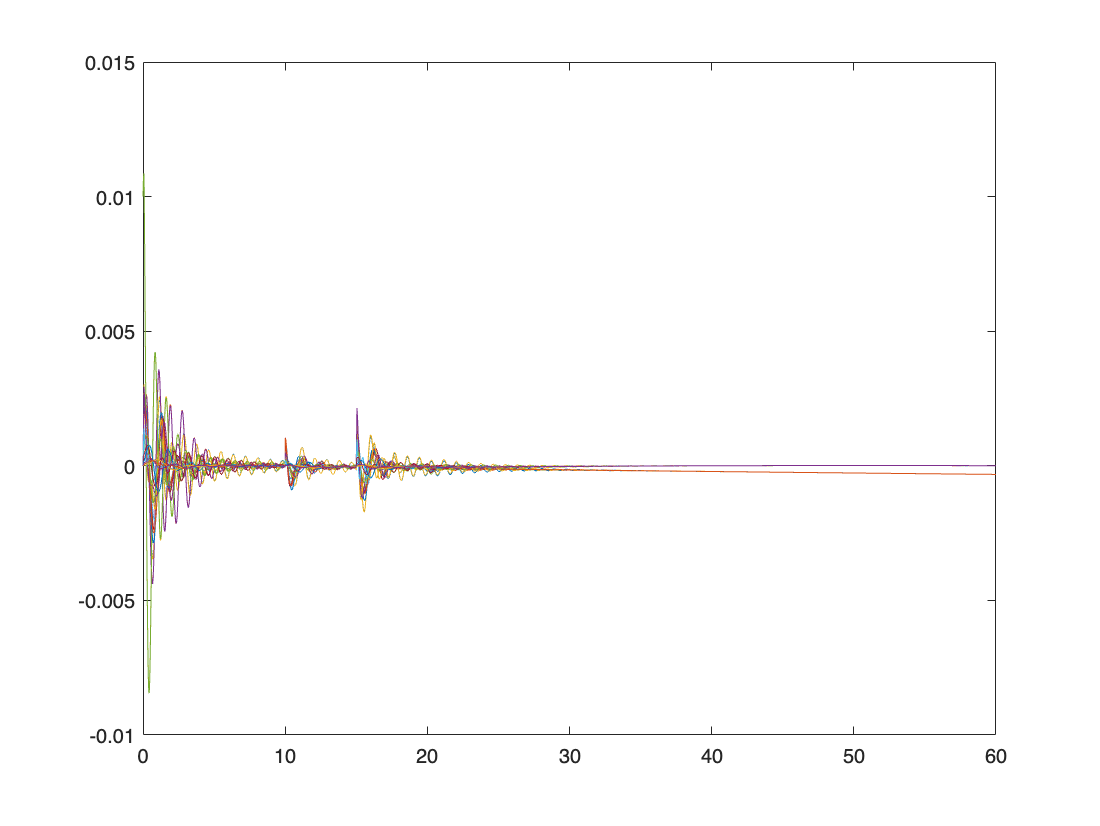

%Get graph for frequency deviation of all generators
n = numel(generator_idx);
for i = 1:n
    plot(out1.t,out1.X{i}(:,2));
    hold on;
end